## Autonomous Unmanned Aerial Systems

### Conceptual Design of a Quadrotor

### Homework 2

Due: 15/03/2026

#### Student Details:

Name: Md Tahseen Aslam                        Roll No: 251010069                 Dept: AE-UAS(Autonomy)

Email: tahseenaslam25@iitk.ac.in            Mobile No: +91-8001156771

% -------------------------------------
% Quadrotor Conceptual Design 
% -------------------------------------

clear; clc; close all;

%% Mission Parameters & Constants
Payload = 0.300;                  % Payload weight (kg)
Endurance_min = 20;               % Hover endurance (minutes)
Endurance_s = Endurance_min * 60; % (seconds)
rho = 1.225;                      % Air density at sea level (kg/m^3)
eta_m = 0.80;                     % Motor efficiency

% BEMT Constants 
Cl_alpha = 5.73; 
Cd0 = 0.01;

%% Parameter Sweep Setup (The "Guesses")
radius_vec = 0.05 : 0.02 : 0.25;      % Rotor radius (m) 
theta0_vec = 18 : 2 : 26;             % Root pitch angle (degrees)
aspect_ratio_vec = 6 : 1 : 16;        % Aspect ratio (R/c)
Nb_vec = [2, 3, 4];                   % Number of blades
n_cells_vec = [3, 4, 6];              % Battery cells (approx 3.7V per cell)
Kv_vec = 1000 : 100 : 3000;            % Motor Kv rating sweep (RPM/V)

results = []; % allocate table for valid converged designs


%% LOCAL FUNCTIONS

function [Thrust, Power] = BEMT_Solver(R, c, Nb, RPM, theta_0_deg, rho, Cl_alpha, Cd0)
    % Vectorized BEMT Solver
    Omega = RPM * (2*pi/60);
    x_root = 0.2; 
    N_elements = 100;
    
    x = linspace(x_root, 1, N_elements); 
    r = x * R; 
    
    theta_vec = deg2rad(theta_0_deg - 17 .* x); 
    sigma_vec = (Nb * c) / (pi * R) * ones(1, N_elements);
    
    A = 4 .* x;
    B = 0.5 .* sigma_vec .* Cl_alpha .* x;
    C = 0.5 .* sigma_vec .* Cl_alpha .* (x.^2) .* theta_vec;
    
    discr = B.^2 + 4 .* A .* C;
    discr(discr < 0) = 0; % Force discr >= 0
    
    lambda_vec = (-B + sqrt(discr)) ./ (2 .* A);
    Cl_vec = Cl_alpha .* (theta_vec - (lambda_vec ./ x));
    
    dT_dr = 0.5 .* rho .* Nb .* (Omega .* r).^2 .* c .* Cl_vec;
    dD_dr = 0.5 .* rho .* Nb .* (Omega .* r).^2 .* c .* Cd0;
    
    dQp_dr = r .* dD_dr;               
    dQi_dr = dT_dr .* lambda_vec .* R; 
    dQ_dr = dQp_dr + dQi_dr;           
    
    Thrust = trapz(r, dT_dr);
    Torque = trapz(r, dQ_dr);
    Power = Torque * Omega;
end


% Weigth Calculation

function [W_rotor, W_motor, W_esc, W_batt, W_frame] = Calculate_Weights(R, c, Nb, P_max, I_max, E_total_Wh, V_batt, Kv)
    R_cm = R * 100;                                
    sigma = (Nb * c) / (pi * R);                   
    S_cells = round(V_batt / 3.7);                 
    C_mAh = (E_total_Wh / V_batt) * 1000;          
    
    % Rotor
    m_rotor_g = 0.0195 * (R_cm^2.0859) * (sigma^-0.2038) * (Nb^0.5344);
    W_rotor = m_rotor_g / 1000; 
    
    % Battery
    m_batt_g = 0.0418 * (C_mAh^0.9327) * (S_cells^1.0725);
    W_batt = m_batt_g / 1000; 
    
    % Motor (with corrected log10 equation from UMD paper)
    l_BL = 4.8910 * (I_max^0.1751) * (P_max^0.2476);
    d_BL = 41.45 * (Kv^-0.1919) * (P_max^0.1935);
    m_motor_g = 0.0109 * (Kv^0.5122) * (P_max^-0.1902) * (log10(l_BL)^2.5582) * (log10(d_BL)^12.8502);
    W_motor = m_motor_g / 1000; 
    
    % ESC
    m_esc_g = 0.8013 * (I_max^0.9727);
    W_esc = m_esc_g / 1000; 
    
    % Airframe
    m_frame_g = 1.3119 * (R_cm^1.2767) * (m_batt_g^0.4587);
    W_frame = m_frame_g / 1000; 
end

%% Main Optimization Loop
disp('Starting iterative sizing loop...');

Starting iterative sizing loop...



for R = radius_vec
    for theta_0 = theta0_vec
        for AR = aspect_ratio_vec
            for Nb = Nb_vec
                
                % Geometric variables
                chord = R / AR; 
                
                % --- PRE-EVALUATE ROTOR AT 1000 RPM ---
                [T_ref, P_ref] = BEMT_Solver(R, chord, Nb, 1000, theta_0, rho, Cl_alpha, Cd0);
                
                % Safety check: If geometry produces zero/negative thrust, skip it
                if T_ref <= 0 || P_ref <= 0
                    continue; 
                end
                
                for n_cells = n_cells_vec
                    V_battery = n_cells * 3.7; 
                    
                    for Kv = Kv_vec
                        
                        % Initial GTOW Guess (3x Payload)
                        GTOW_guess = 3 * Payload; 
                        tolerance = 0.001; 
                        error_val = 1;
                        iter = 0;
                        max_iter = 100;
                        
                        % The Sizing Convergence Loop
                        while error_val > tolerance && iter < max_iter
                            iter = iter + 1;
                            
                            % Hover Scaling
                            T_hover_req = (GTOW_guess * 9.81) / 4; 
                            
                            Hover_RPM = 1000 * sqrt(T_hover_req / T_ref);
                            P_hover_aero = P_ref * (Hover_RPM / 1000)^3;
                            
                            %  Max Thrust Scaling (2x Hover)
                            T_max_req = T_hover_req * 2;
                            Max_RPM = 1000 * sqrt(T_max_req / T_ref);
                           
                            % RPM CONSTRAINT: Reject design if the motor physically cannot spin this fast on this battery
                            if Max_RPM > (V_battery * Kv * 0.90)
                                GTOW_guess = 100; % Force rejection
                                break; 
                            end
                            
                            P_max_aero = P_ref * (Max_RPM / 1000)^3;
                            
                            % Electrical Power Requirements
                            P_hover_elec = P_hover_aero / eta_m;
                            P_max_elec = P_max_aero / eta_m;
                            I_max = P_max_elec / V_battery; 
                            
                            E_total_Wh = (P_hover_elec * 4 * Endurance_s) / 3600; 
                            
                            % Component Weight Estimation
                            [W_rotor, W_motor, W_esc, W_batt, W_frame] = Calculate_Weights(R, chord, Nb, P_max_elec, I_max, E_total_Wh, V_battery, Kv);
                            
                            % Update GTOW and check convergence
                            Electronics_Misc = 0.050; % 50g 
                            GTOW_new = Payload + W_frame + W_batt + Electronics_Misc + 4*(W_rotor + W_motor + W_esc);
                            
                            % relaxation
                            error_val = abs(GTOW_new - GTOW_guess);
                            GTOW_guess = GTOW_guess + 0.20 * (GTOW_new - GTOW_guess); 
                        end
                        
                        % Save valid results (Tracking 15 specific parameters)
                        if iter < max_iter && GTOW_guess < 5.0 
                            results = [results; R, theta_0, AR, Nb, n_cells, GTOW_guess, W_batt, W_motor, Hover_RPM, W_rotor, W_esc, W_frame, Kv, P_max_elec, I_max];
                        end
                        
                    end % End Kv Loop
                end % End Battery Loop
            end % End Blade Loop
        end % End Aspect Ratio Loop
    end % End Pitch Loop
end % End Radius Loop

disp('Optimization Complete!');

Optimization Complete!



%% Post-Processing & Outputs
if isempty(results)
    error('No designs converged! Check your empirical weight bounds.');
end

%% Find the Optimal Design (Minimum GTOW)
[min_GTOW, opt_idx] = min(results(:, 6));
Opt = results(opt_idx, :);

% OUTPUT 1 & 2: OPTIMAL QUADROTOR DESIGN SPECIFICATIONS 
Parameters = {
    'Minimum GTOW'; 'Payload'; 'Frame Weight'; 'Battery Weight'; 
    'Motor Weight (Each)'; 'Rotor Weight (Each)'; 'ESC Weight (Each)'; 
    'Rotor Radius'; 'Chord'; 'Aspect Ratio'; 'Number of Blades'; 
    'Root Pitch (theta0)'; 'Battery Cells'; 'Battery Voltage'; 
    'Hover RPM'; 'Disc Loading'; 'Motor Kv Rating'; 
    'Max Power (per motor)'; 'Max Current (per ESC)'
};

Values = {
    sprintf('%.2f', Opt(6)*1000); 
    sprintf('%.2f', 300); 
    sprintf('%.2f', Opt(12)*1000); 
    sprintf('%.2f', Opt(7)*1000); 
    sprintf('%.2f', Opt(8)*1000); 
    sprintf('%.2f', Opt(10)*1000); 
    sprintf('%.2f', Opt(11)*1000); 
    sprintf('%.3f', Opt(1)); 
    sprintf('%.3f', Opt(1)/Opt(3)); 
    sprintf('%d', Opt(3)); 
    sprintf('%d', Opt(4)); 
    sprintf('%d', Opt(2)); 
    sprintf('%d', Opt(5)); 
    sprintf('%.1f', Opt(5) * 3.7); 
    sprintf('%.0f', Opt(9)); 
    sprintf('%.2f', (Opt(6)*9.81)/(4*pi*Opt(1)^2)); 
    sprintf('%.0f', Opt(13)); 
    sprintf('%.2f', Opt(14)); 
    sprintf('%.2f', Opt(15))
};

Units = {
    'grams'; 'grams'; 'grams'; 'grams'; 'grams'; 'grams'; 'grams'; 
    'm'; 'm'; '-'; '-'; 'deg'; 'S'; 'V'; 'RPM'; 'N/m^2'; 'RPM/V'; 
    'Watts'; 'Amps'
};

OptimalDesignTable = table(Parameters, Values, Units, ...
    'VariableNames', {'Optimal Design_Parameter', 'Calculated_Value', 'Unit'});

% Print the table
disp(OptimalDesignTable);

    Optimal Design_Parameter     Calculated_Value      Unit   
    _________________________    ________________    _________

    {'Minimum GTOW'         }       {'816.40'}       {'grams'}
    {'Payload'              }       {'300.00'}       {'grams'}
    {'Frame Weight'         }       {'224.68'}       {'grams'}
    {'Battery Weight'       }       {'163.54'}       {'grams'}
    {'Motor Weight (Each)'  }       {'11.71' }       {'grams'}
    {'Rotor Weight (Each)'  }       {'4.36'  }       {'grams'}
    {'ESC Weight (Each)'    }       {'3.28'  }       {'grams'}
    {'Rotor Radius'         }       {'0.090' }       {'m'    }
    {'Chord'                }       {'0.015' }       {'m'    }
    {'Aspect Ratio'         }       {'6'     }       {'-'    }
    {'Number of Blades'     }       {'2'     }       {'-'    }
    {'Root Pitch (theta0)'  }       {'26'    }       {'deg'  }
    {'Battery C

%% Print Full Results Table

% Define the column names (15 columns)
columnNames = {'Radius_m', 'Theta0_deg', 'AspectRatio', 'NumBlades', ...
               'Cells', 'GTOW_kg', 'W_Battery_kg', 'W_Motor_kg', ...
               'Hover_RPM', 'W_Rotor_kg', 'W_ESC_kg', 'W_Frame_kg', ...
               'Kv_Rating', 'P_max_Watts', 'I_max_Amps'};

% Convert the raw numeric matrix into a MATLAB Table object
results_table = array2table(results, 'VariableNames', columnNames);

% Sort the table so the lowest GTOW (best design) is at the top
results_table = sortrows(results_table, 'GTOW_kg');

% Display the top 25 optimal designs
disp(head(results_table, 25));

    Radius_m    Theta0_deg    AspectRatio    NumBlades    Cells    GTOW_kg    W_Battery_kg    W_Motor_kg    Hover_RPM    W_Rotor_kg    W_ESC_kg     W_Frame_kg    Kv_Rating    P_max_Watts    I_max_Amps
    ________    __________    ___________    _________    _____    _______    ____________    __________    _________    __________    _________    __________    _________    ___________    __________

      0.09          26             6             2          3       0.8164      0.16354

fprintf('CONVERGED DESIGNS TABLE (Sorted by Minimum GTOW)\n');

CONVERGED DESIGNS TABLE (Sorted by Minimum GTOW)


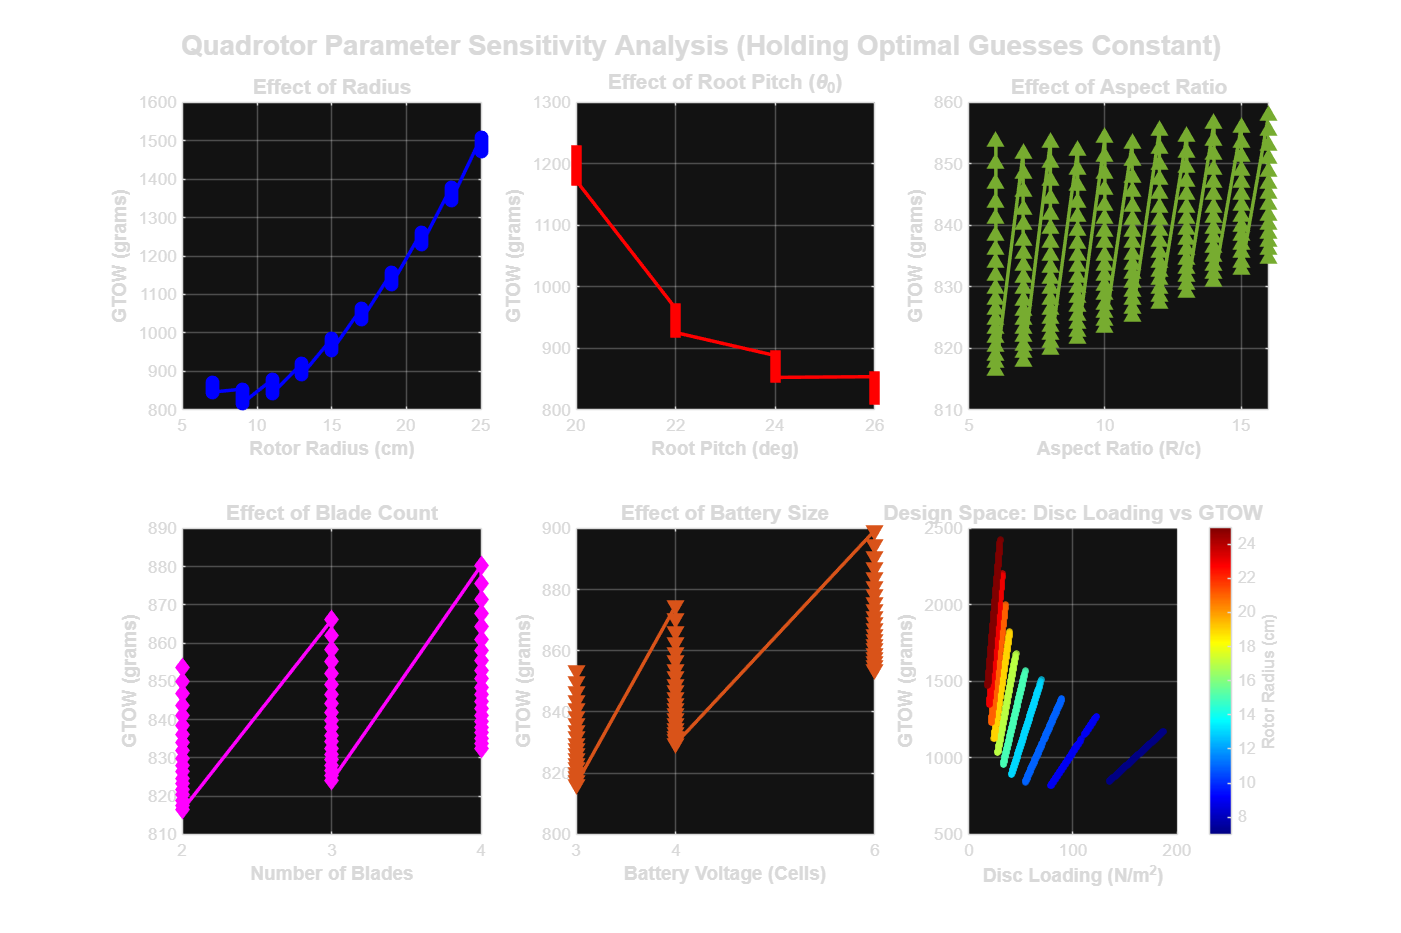

%% Plots

% Extract the optimal parameters to hold constant for the sensitivity analysis
opt_R     = Opt(1);
opt_Theta = Opt(2);
opt_AR    = Opt(3);
opt_Nb    = Opt(4);
opt_Cells = Opt(5);

% figure
figure('Name', 'Parameter Sensitivity Analysis', 'Position', [100, 100, 1200, 800], 'Color', 'w');

% -------------------------------------------------------------------------
% GRAPH 1: Effect of Rotor Radius (Holding others constant)
% -------------------------------------------------------------------------
subplot(2, 3, 1);
idx = (results(:,2)==opt_Theta & results(:,3)==opt_AR & results(:,4)==opt_Nb & results(:,5)==opt_Cells);
plot_data = sortrows(results(idx, :), 1); 
plot(plot_data(:,1)*100, plot_data(:,6)*1000, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b', 'Color', 'b');
xlabel('Rotor Radius (cm)', 'FontWeight', 'bold'); 
ylabel('GTOW (grams)', 'FontWeight', 'bold');
title('Effect of Radius', 'FontSize', 12); 
grid on;

% -------------------------------------------------------------------------
% GRAPH 2: Effect of Root Pitch (Holding others constant)
% -------------------------------------------------------------------------
subplot(2, 3, 2);
idx = (results(:,1)==opt_R & results(:,3)==opt_AR & results(:,4)==opt_Nb & results(:,5)==opt_Cells);
plot_data = sortrows(results(idx, :), 2);
plot(plot_data(:,2), plot_data(:,6)*1000, '-s', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'Color', 'r');
xlabel('Root Pitch (deg)', 'FontWeight', 'bold'); 
ylabel('GTOW (grams)', 'FontWeight', 'bold');
title('Effect of Root Pitch (\theta_0)', 'FontSize', 12); 
grid on;

% -------------------------------------------------------------------------
% GRAPH 3: Effect of Aspect Ratio (Holding others constant)
% -------------------------------------------------------------------------
subplot(2, 3, 3);
idx = (results(:,1)==opt_R & results(:,2)==opt_Theta & results(:,4)==opt_Nb & results(:,5)==opt_Cells);
plot_data = sortrows(results(idx, :), 3);
plot(plot_data(:,3), plot_data(:,6)*1000, '-^', 'LineWidth', 2, 'MarkerFaceColor', '#77AC30', 'Color', '#77AC30');
xlabel('Aspect Ratio (R/c)', 'FontWeight', 'bold'); 
ylabel('GTOW (grams)', 'FontWeight', 'bold');
title('Effect of Aspect Ratio', 'FontSize', 12); 
grid on;

% -------------------------------------------------------------------------
% GRAPH 4: Effect of Number of Blades (Holding others constant)
% -------------------------------------------------------------------------
subplot(2, 3, 4);
idx = (results(:,1)==opt_R & results(:,2)==opt_Theta & results(:,3)==opt_AR & results(:,5)==opt_Cells);
plot_data = sortrows(results(idx, :), 4);
plot(plot_data(:,4), plot_data(:,6)*1000, '-d', 'LineWidth', 2, 'MarkerFaceColor', 'm', 'Color', 'm');
xlabel('Number of Blades', 'FontWeight', 'bold'); 
ylabel('GTOW (grams)', 'FontWeight', 'bold');
title('Effect of Blade Count', 'FontSize', 12); 
xticks([2 3 4]); grid on;

% -------------------------------------------------------------------------
% GRAPH 5: Effect of Battery Cells (Holding others constant)
% -------------------------------------------------------------------------
subplot(2, 3, 5);
idx = (results(:,1)==opt_R & results(:,2)==opt_Theta & results(:,3)==opt_AR & results(:,4)==opt_Nb);
plot_data = sortrows(results(idx, :), 5);
plot(plot_data(:,5), plot_data(:,6)*1000, '-v', 'LineWidth', 2, 'MarkerFaceColor', '#D95319', 'Color', '#D95319');
xlabel('Battery Voltage (Cells)', 'FontWeight', 'bold'); 
ylabel('GTOW (grams)', 'FontWeight', 'bold');
title('Effect of Battery Size', 'FontSize', 12); 
xticks([3 4 6]); grid on;

% -------------------------------------------------------------------------
% GRAPH 6: Overall Design Space (Output 4: Disc Loading Overview)
% -------------------------------------------------------------------------
subplot(2, 3, 6);
Disc_Loading_All = (results(:,6).*9.81) ./ (4 .* pi .* results(:,1).^2);
scatter(Disc_Loading_All, results(:,6)*1000, 15, results(:,1)*100, 'filled', 'MarkerFaceAlpha', 0.7);
colormap(jet); 
c = colorbar; 
c.Label.String = 'Rotor Radius (cm)';
c.Label.FontWeight = 'bold';
xlabel('Disc Loading (N/m^2)', 'FontWeight', 'bold'); 
ylabel('GTOW (grams)', 'FontWeight', 'bold');
title('Design Space: Disc Loading vs GTOW', 'FontSize', 12); 
grid on;

% Adjust layout to prevent text overlapping
sgtitle('Quadrotor Parameter Sensitivity Analysis (Holding Optimal Guesses Constant)', 'FontWeight', 'bold', 'FontSize', 16);

writetable(results_table,'design_Data.csv','Delimiter',',','QuoteStrings','all')
type 'design_Data.csv'


Radius_m,Theta0_deg,AspectRatio,NumBlades,Cells,GTOW_kg,W_Battery_kg,W_Motor_kg,Hover_RPM,W_Rotor_kg,W_ESC_kg,W_Frame_kg,Kv_Rating,P_max_Watts,I_max_Amps
0.09,26,6,2,3,0.816404026209736,0.163536675039167,0.0117130686803406,7849.33850101646,0.00436431357749691,0.00328270734618327,0.224681554217114,3000,47.309546790048,4.26212133243676
0.09,26,6,2,3,0.817606673124836,0.163873325416171,0.0118709783573084,7855.10944343584,0.00436431357749691,0.00328975512401573,0.224893594474292,2900,47.4139714297101,4.27152895763154
0.09,26,7,2,3,0.81787313575949,0.163990783470936,0.0117494716751823,8282.58334662437,0.00450359888541788,0.00329221425534031,0.224967520291959,3000,47.4504090597689,4.2748116270062
0.09,26,6,2,3,0.818863303272564,0.164225287410466,0.0120359899624417,7861.13472098005,0.00436431357749691,0.00329712411459747,0.22511502683055,2800,47.5231620891037,4.28136595397331
0.09,26,7,2,3,0.81926136613696,0.164384623313286,0.0119123485451123,8289.68677455835,0.00450359888541788,0.0033004603